***Integrantes***:

- Naysla tatiana torres Cortes

- Ariel David Herrera Ahumda

# MÉTODO RECTÁNGULO

**Ejercicio 1**

%datos iniciales
a=2

a = 2

b=5

b = 5

h=0.5

h = 0.5000

%Hallar número de intervalos
n=Intervalo(a,b,h)

n = 6

cotaMin=a;
cotaMax =cotaMin+h;
AreaTotal = 0;
for i= 1:n
   %intervalo en x
   strcat('(',num2str(cotaMin),' - ',num2str(cotaMax),')')
   %Punto Medio
   p=PuntoMedio(cotaMin,cotaMax);
   %validar funcion en ese punto 
   f = EvaluarFuncion(p);
   %hallar áreas
   a =Area(f,h);
   %Sumar las áreas
   AreaTotal=AreaTotal+a;
   cotaMin=cotaMax;
   cotaMax = cotaMax+h;   
end

ans = '(2 -2.5)'

ans = '(2.5 -3)'

ans = '(3 -3.5)'

ans = '(3.5 -4)'

ans = '(4 -4.5)'

ans = '(4.5 -5)'

%Resultado area total
strcat('El área total de la funcion cuando la cota inferior es ',num2str(a))

ans = 'El área total de la funcion cuando la cota inferior es1.5581'

strcat(' y la cota superior es  ',num2str(b),' es Areatotal: ',num2str(AreaTotal))

ans = ' y la cota superior es5 es Areatotal:7.328'

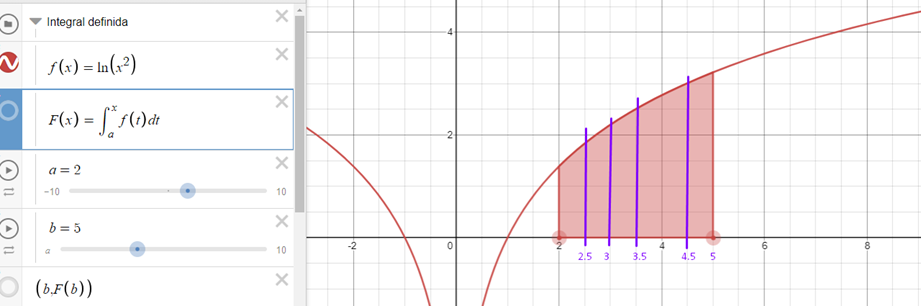

***FUNCIONES***  

function [n]=Intervalo(a,b,h)
    n= (b-a)/h;
end
function [p]=PuntoMedio(a,b)
    p= (b+a)/2;
end
function f = EvaluarFuncion(x)    
    f = log(x^2);
end
function a = Area (f,h) 
    a = f*h;
end